# **Substate state-space**

# **MATLAB function examples**

close all
clearvars

List of functions for the exam:

- sys = ss(F, G, H, D, Ts); or sys = ss(W);

- eigenvalues = eig(sys);

- O = obsv(sys);

- R = ctrb(sys);

- obs_rank = rank(O);

- W = tf(sys);  or  W = tf(num_coeffs, den_coeffs, Ts);

- W = zpk(W);

- zeros_vec = zero(W);

- pole_vec = pole(W);

- sys_gain = dcgain(W);

- bode(sys)

- impulse(sys)

- step(sys)

- lsim(sys)

- sys = n4sid(data) *

- [U, S, V] = svd(Hqd) *

*explained in the pendulum example and not in this file.

## System defined from system matrices (state-space)

Given the following system, define it in MATLAB as a discrete time system with sampling time 1 s:


$$F=\left\lbrack \begin{array}{cc}
0\ldotp 999 & -0\ldotp 001\\
0\ldotp 002 & 0
\end{array}\right\rbrack$$
     
$$H=\left\lbrack \begin{array}{cc}
0\ldotp 5 & 2\ldotp 5
\end{array}\right\rbrack$$
    
$$G=\left\lbrack \begin{array}{c}
0\ldotp 002\\
0
\end{array}\right\rbrack$$
     
$$D=0$$


% Define the system matrices
F = [0.999 -0.001; 0.002 1];
G = [0.002; 0];
H = [0.5 2.5];
D = 0;

% Define system sampling time
Ts = 1; % [s]

% Define system object
sys = ss(F, G, H, D, Ts);
% If Ts is not provided, sys will be in continuous time. If Ts = -1, the
% sampling period will remain unspecified but the system will be in discrete time.

% We can display the defined system:
sys

sys =
 
  A = 
           x1      x2
   x1   0.999  -0.001
   x2   0.002       1
 
  B = 
          u1
   x1  0.002
   x2      0
 
  C = 
        x1   x2
   y1  0.5  2.5
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



#### We can now compute the eigenvalues of the system:

eigenvalues = eig(sys);

% Display the eigenvalues:
eigenvalues

eigenvalues =    0.9995 + 0.0013i
   0.9995 - 0.0013i


% Check whether eigenvalues are within unit circle
if all(abs(eigenvalues) < 1)
    disp("Asymptotically stable system");
elseif all(abs(eigenvalues) <= 1)
    disp("Simply stable system");
else
    disp("Unstable system");
end

Asymptotically stable system


#### We can check controllability and observability of the system:

O = obsv(F, H)

O =     0.5000    2.5000
    0.5045    2.4995


R = ctrb(F, G)

R =     0.0020    0.0020
         0    0.0000



% If you do not have matrices F, G and H but you have the system object,
% you can use:
O = obsv(sys.A, sys.C);
R = ctrb(sys.A, sys.B);

% One further way to call these functions:
O = obsv(sys);
R = ctrb(sys);

% To check if the system is observable:
nx = size(sys.A, 1); % or nx = size(F, 1)
if rank(O) == nx
    disp("System is observable");
else
    disp("System is NOT observable");
end

System is observable


    
% To check reachability:
nx = size(sys.A, 1); % or nx = size(F, 1)
if rank(R) == nx
    disp("System is reachable");
else
    disp("System is NOT reachable");
end

System is reachable


#### We can now turn the state space model into a transfer function:

W = tf(sys);
% tf command defines a transfer function

% Display W
W

W =
 
    0.001 z - 0.00099
  ---------------------
  z^2 - 1.999 z + 0.999
 
Sample time: 1 seconds
Discrete-time transfer function.




% If you want to clearly see zero-pole-gain:
W = zpk(W);
% or W = zpk(sys);

% Display W
W

W =
 
      0.001 (z-0.99)
  ----------------------
  (z^2 - 1.999z + 0.999)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



% To compute separately zeros, poles and gain:
sys_zeros = zero(sys)

sys_zeros = 0.9900

% The same function can be also called using a transfer function and not a
% discrete time system object
sys_zeros = zero(W)

sys_zeros = 0.9900


sys_poles = pole(W) % or pole(sys)

sys_poles =    0.9995 + 0.0013i
   0.9995 - 0.0013i


sys_gain = dcgain(W) % or dcgain(sys)

sys_gain = 5.0000

#### We can check the bode diagram of the system:

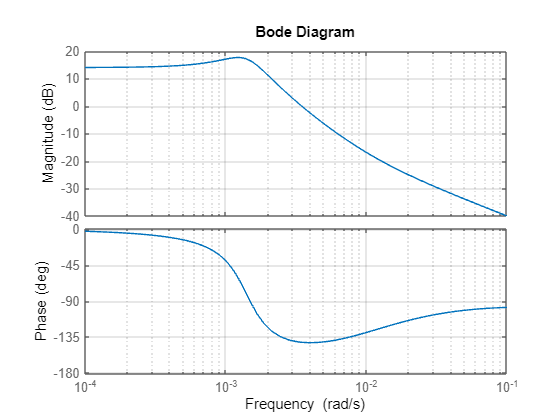

bode(sys) % or bode(W)
hold on; grid minor; clf;

#### We can now simulate the system over time and plot the results:

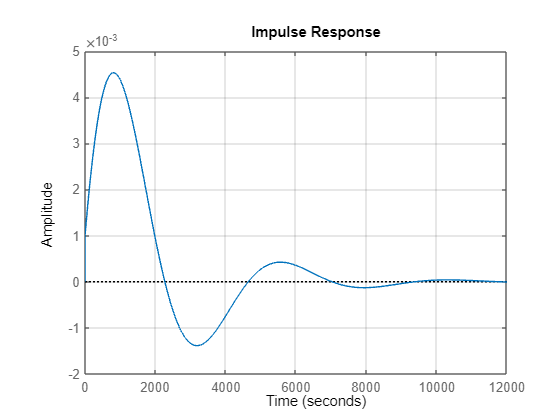

% To plot the impulse response of the system:
impulse(sys)
hold on; grid minor; clf;


% We can also get the impulse response vectors in time:
[ir_data, ir_time] = impulse(sys);
% Display ir_data
ir_data

ir_data =          0
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0011
    0.0011
    0.0011


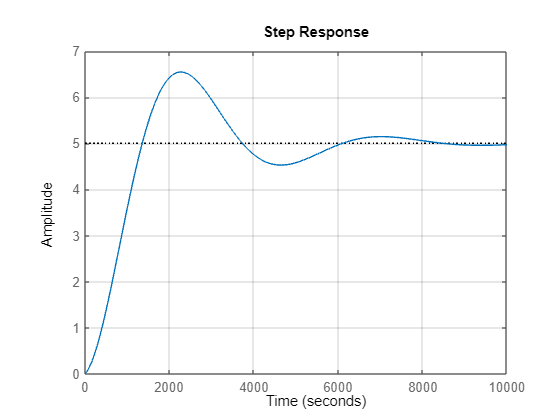


% The same can be done for the step response:
step(sys)
hold on; grid minor; clf;


% We can also get the step response vectors in time:
[step_data, step_time] = step(sys);
% Display ir_data
step_data

step_data =          0
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0011
    0.0011
    0.0011


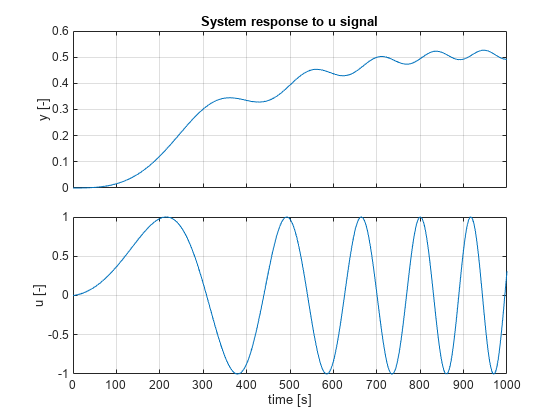


% Finally, we can simulate the system with any input signal:

% Define time vector time_vec
end_time = 1000; 
time_vec = (0:Ts:end_time)';

% Define u_vec (vector of the input)
f_start = 0.0001; f_end = 0.01; amplitude = 1;
u_vec = amplitude*sin(2*pi*(f_start*time_vec + (f_end-f_start)/end_time/2*time_vec.^2));

% Simulate system response
y_vec = lsim(sys, u_vec, time_vec);

%% Experiment plot
figure;
tiledlayout(2, 1, 'TileSpacing', 'compact');

ax(1) = nexttile; hold on; grid on; box on;
title('System response to u signal');
plot(time_vec, y_vec);
ylabel('y [-]');
xticklabels(''); 

ax(2) = nexttile; hold on; grid on; box on;
xlabel('time [s]');
ylabel('u [-]');
plot(time_vec, u_vec);

linkaxes(ax, 'x'); clear ax;  clf;

## System defined from transfer function

Define a discrete time system of the following transfer function (sampling time 1 s):

$W\left(z\right)=\frac{1e-3\cdot z-0\ldotp 99e-3}{z^2 -1\ldotp 999z+0\ldotp 999}$  (Positive power notation)

% Define the coefficients of the numerator and denominator.
numerator_coeffs = [1.0000   -0.9900]*1e-3;
denominator_coeffs = [1.0000   -1.999 0.999];

% Define sampling time
Ts = 1; % [s]

W = tf(numerator_coeffs, denominator_coeffs, Ts)

W =
 
    0.001 z - 0.00099
  ---------------------
  z^2 - 1.999 z + 0.999
 
Sample time: 1 seconds
Discrete-time transfer function.




% Now we can compute one possibile realization in state-space of the system
% by using the function ss:
sys = ss(W)

sys =
 
  A = 
           x1      x2
   x1   1.999  -0.999
   x2       1       0
 
  B = 
           u1
   x1  0.0625
   x2       0
 
  C = 
             x1        x2
   y1     0.016  -0.01584
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



## Question examples:

- Given the following discrete-time system: $F=\left\lbrack \begin{array}{cc}
0 & 2\\
\frac{1}{2} & 3
\end{array}\right\rbrack$     $H=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack$    $G=\left\lbrack \begin{array}{c}
\frac{1}{2}\\
\frac{1}{2}
\end{array}\right\rbrack$     $D=0$, define it as discrete state-space system in MATLAB and check the observability of the system.

- Given a MATLAB discrete-time state-space system named *sys,* compute the eigenvalues and show the transfer function in zero-pole-gain form.

- Given the following transfer function: $W\left(z\right)=\frac{0\ldotp 5\cdot z-0\ldotp 5}{z^2 -3z-1}$, define it in MATLAB and find a state-space realization. Then compute its poles.

- Given the discrete time MATLAB system *sys* and a known input vector* u* and its corresponding time vector *t*, write the code to compute the response of *sys *to *u*.

- Write the MATLAB code to compute the first 10 samples of the impulse response of a known transfer function *W*.